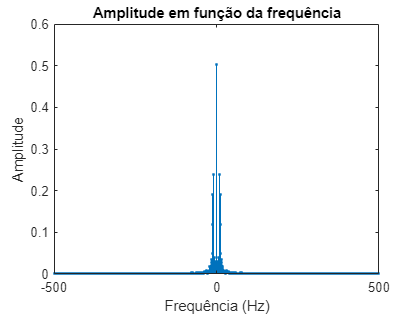

Ta = 0.001;
N = 1000;
[x,t] = GeraSinal(N,Ta);
figure(1)
plot(t,x)
title('Sinal gerado em função do tempo')
xlabel('Tempo(seg)')
ylabel('Sinal')
grid

% 2.
figure(2)
[X,f] = Espetro(x,Ta);

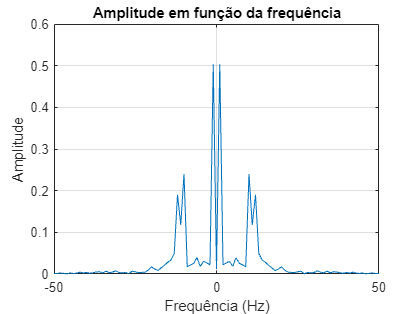

Fa = 1/Ta;
plot(f,abs(X))
xlim([-50,50])
xlabel('Frequência (Hz)')
ylabel('Amplitude')
title('Amplitude em função da frequência')
grid

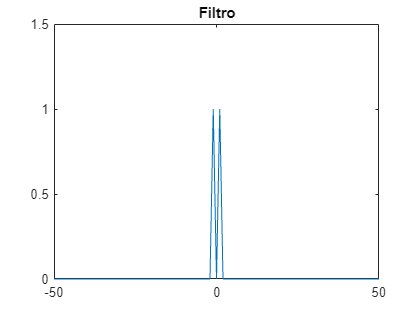


% 3.
fmin = 0;
fmax = 2;

filtro = zeros(1,length(f));
filtro(f>fmin & f<fmax) = 1;
filtro(f>-fmax & f<-fmin) = 1;
filtro = logical(filtro);

figure(3)
plot(f,filtro)
title('Filtro')
xlim([-50,50])
ylim([0,1.5])

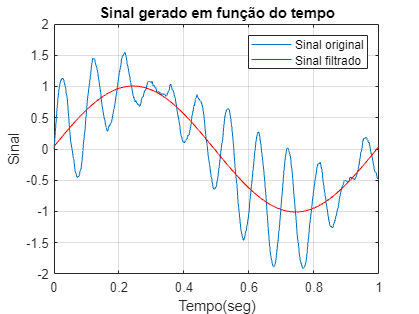


j = 0;
x_filt = X(filtro);
new_x = zeros(length(X),1);
for i = 1:length(filtro)
    if filtro(i) == 1
        j = j + 1;
        new_x(i) = x_filt(j);
    end
end

w = Reconstroi(new_x,f);
figure(1)
hold on
plot(t,w,'r-')
legend('Sinal original','Sinal filtrado')



% Função

function [x,t] = GeraSinal(N,Ta)
phi = normrnd(0,pi,[1,N]);
phi_i1 = zeros(1,N);
for n = 2:N
    phi_i1(n) = phi_i1(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

phi = normrnd(0,pi,[1,N]);
phi_i2 = zeros(1,N);
for n = 2:N
    phi_i2(n) = phi_i2(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

t = (0:N-1)*Ta;
x = sin(2*pi*t) + 0.5*sin(2*pi*10*t + 10*phi_i1) + 0.5*sin(2*pi*12*t + 10*phi_i2);
end